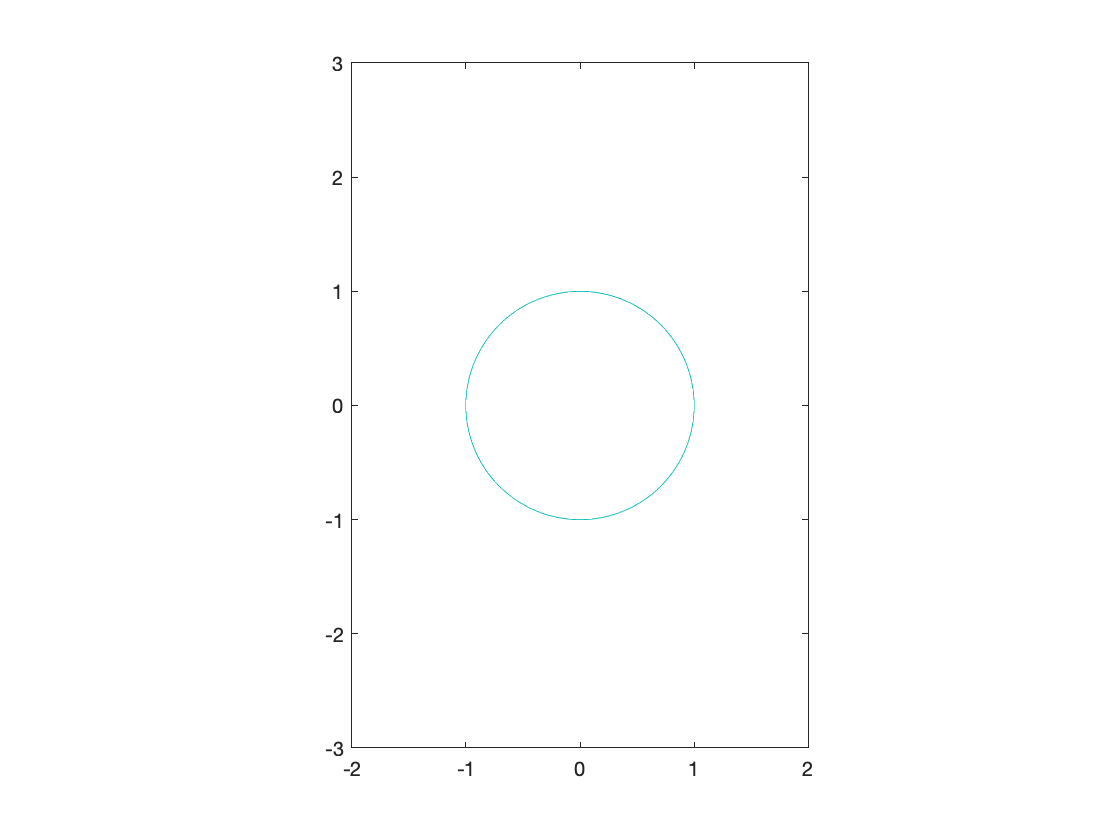

 %% 28.1.2
 
 [x, y] = meshgrid(linspace(-2, 2, 100), linspace(-3, 3, 200));
 f = x.^2 + y.^2 - 1;
 contour(x, y, f, [0 0]);
 axis equal;

## Exercise 28.5

Visualization of a circle

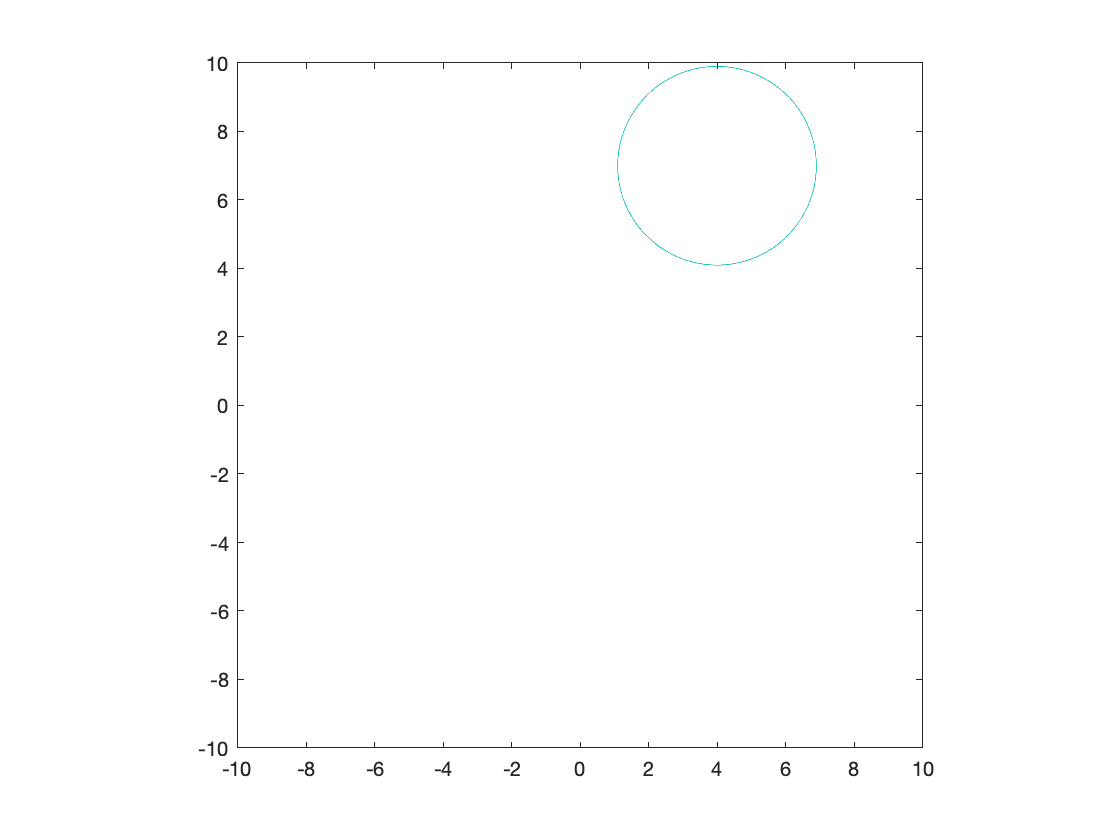

R =2.9;
a = 4;
b = 7;

[x, y] = meshgrid(linspace(-10, 10, 1000), linspace(-10, 10, 1000));
f = (x - a).^2 + (y - b).^2 - R^2;
contour(x, y, f, [0 0]);
axis equal;

## 28.1.3

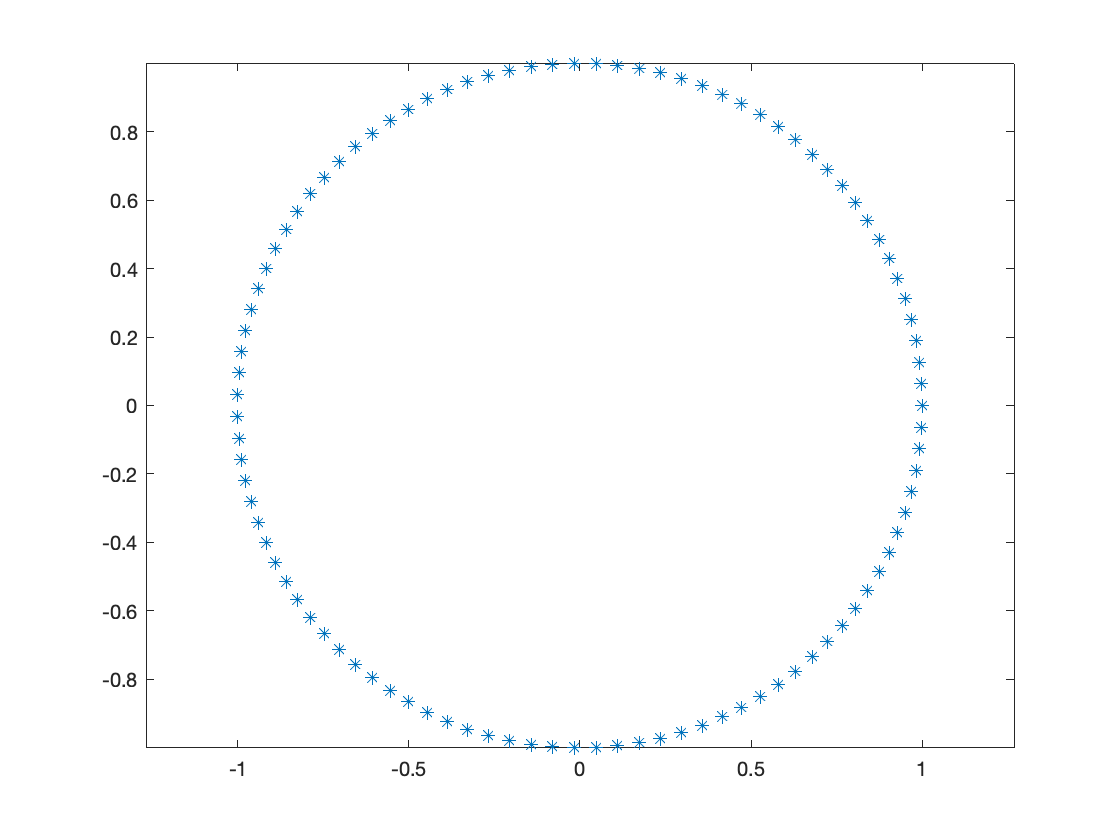

u = linspace(0, 2 * pi, 100);
x = cos(u);
y = sin(u);
plot(x, y, '*');
axis equal;

## Excercise 28.10

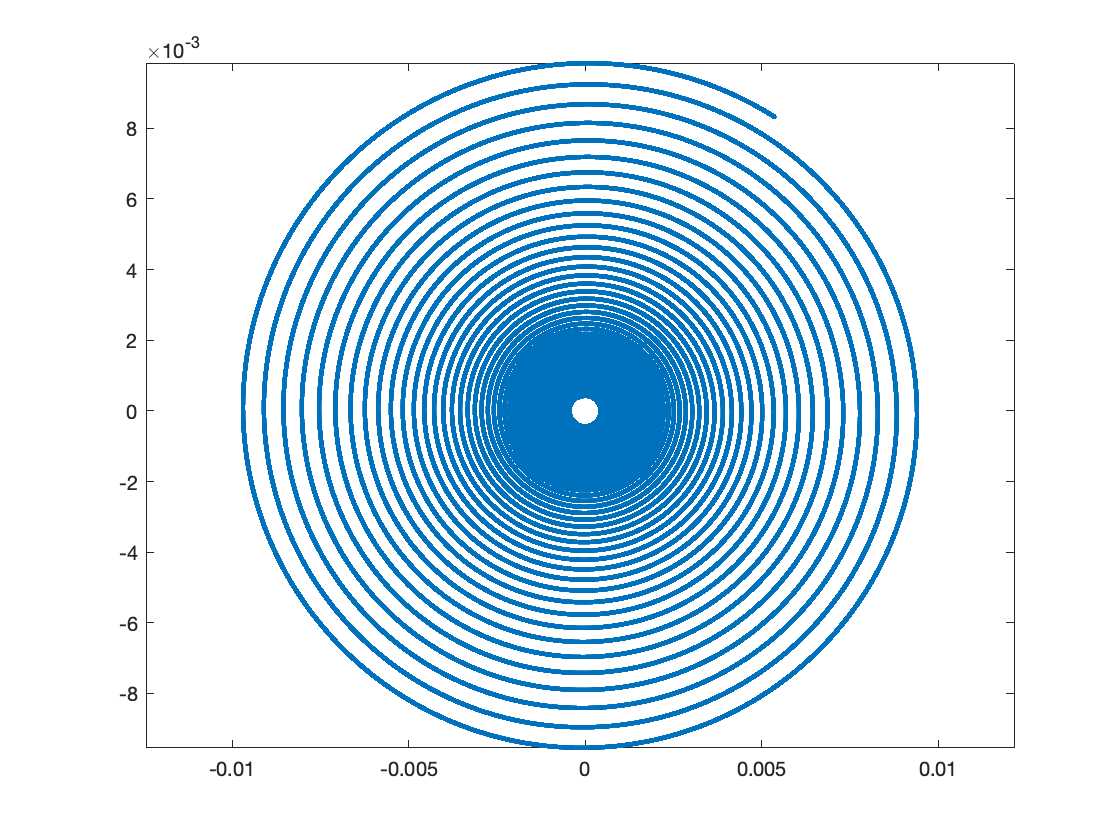

e = exp(1);

a = 10 ^-2;
b = 10 ^-2;

min = 10 ^ 0;
max_num = 10 ^ 2.5;
num_points = 10 ^ 6.2;

u = linspace(min, max_num, num_points);

x = a * e.^(-b * u) .* cos(u);
y = a * e.^(-b * u) .* sin(u);

plot(x, y, '.-');
axis equal;

## Exercise 28.11

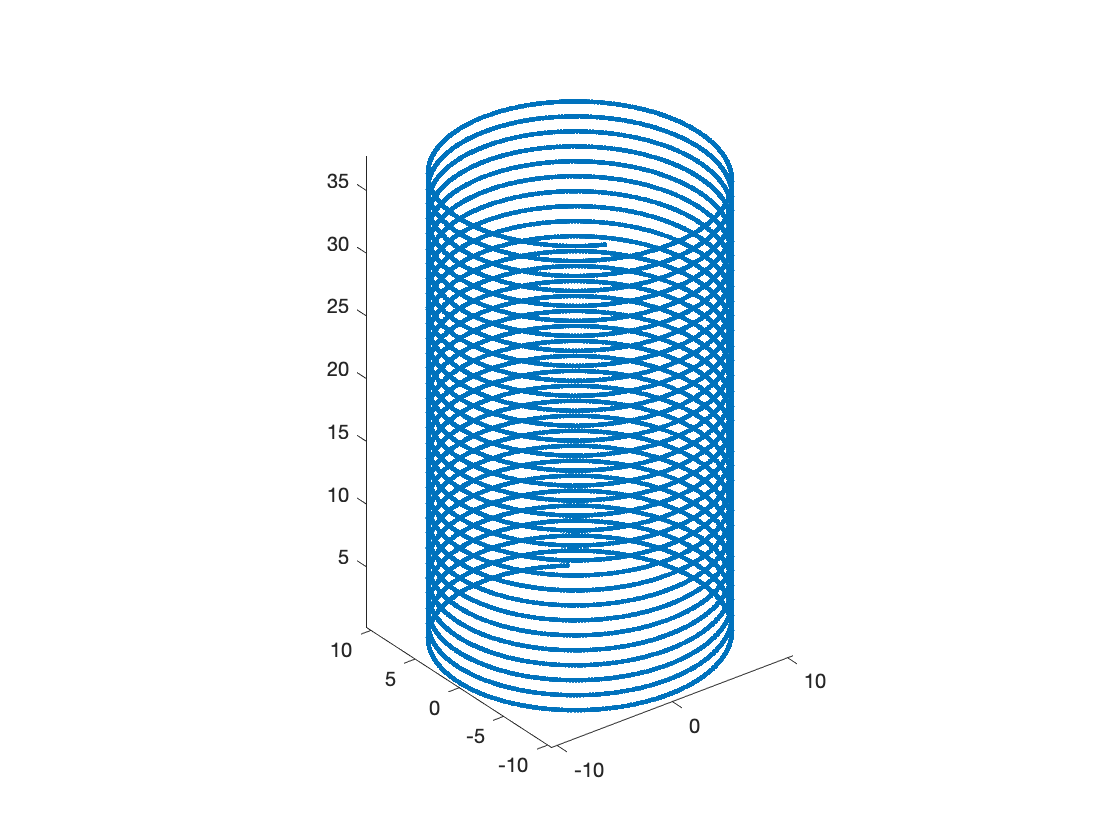

e = exp(1);

a =10.5;
b =0.19;

min = 1;
max_num =199;
num_points = 9369;

u = linspace(min, max_num, num_points);

x = a * cos(u);
y = a * sin(u);
z = b * u;

plot3(x, y, z, '.-');
axis equal;

## 28.1.4

x = [0 1 3 5]';
y = [1 0 2 4]';
plot(x, y, 'r*'); hold on;

% Using orthogonal projection to find line of best fit:
% We want to find a line y = mx + b
% What if we used our vectors and so had \vec{y} = m\vec{x} + b
% There's four equations (one for each data point), so we can't get an
% exact answer
% We can rephrase this is a more convinent form (ones column is to multiply by b):
A = [x ones(size(x))]

A =      0     1
     1     1
     3     1
     5     1


% Need to find: p = [m; b] (parameters): Ap = y
% The best solution is A' * A * p = A' * y
p = (A' * A) \ (A' * y)

p =     0.6949
    0.1864


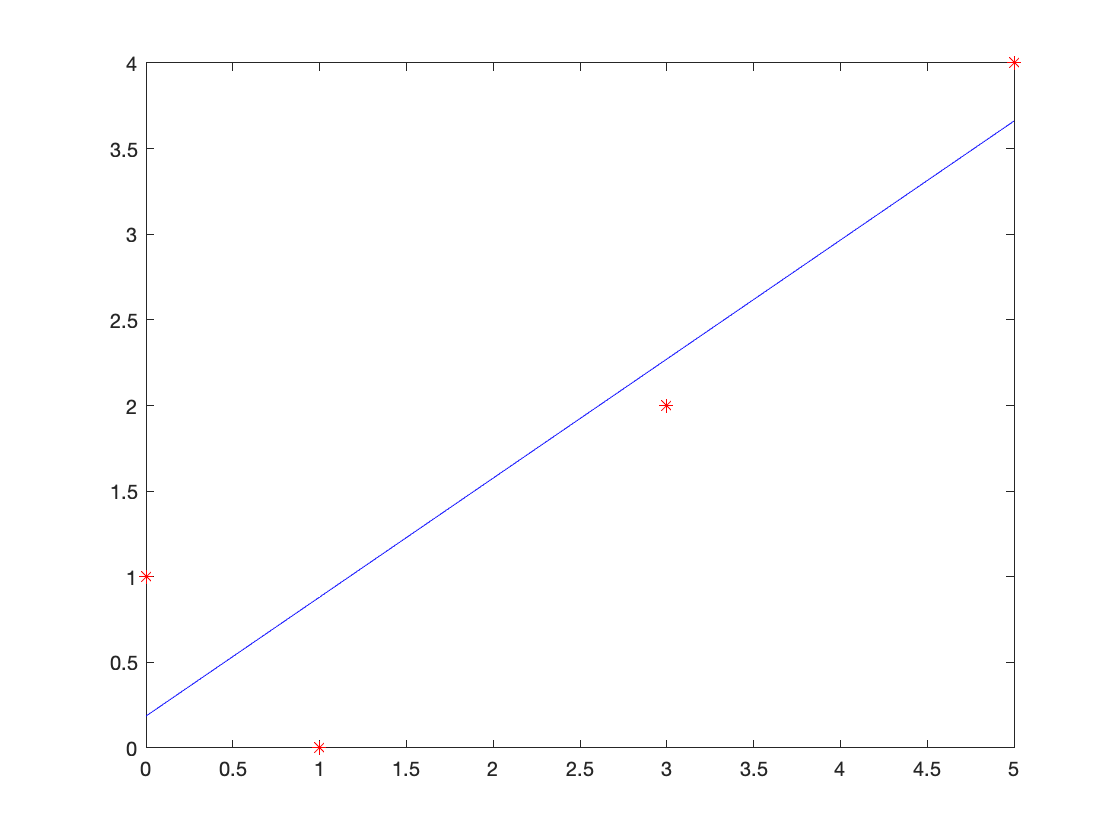


xes = 0:max(x);
y = (p(1) * xes) + p(2);
plot(xes, y, 'b-'); hold off;

%% Exercise 28.12
x = [0 1 3 5]';
y = [1 0 2 4]';
plot(x, y, 'r*'); hold on;
M = [x.^2, x, ones(size(x))]

M =      0     0     1
     1     1     1
     9     3     1
    25     5     1


p = (M' * M) \ (M' * y)

p =     0.1910
   -0.2663
    0.6784


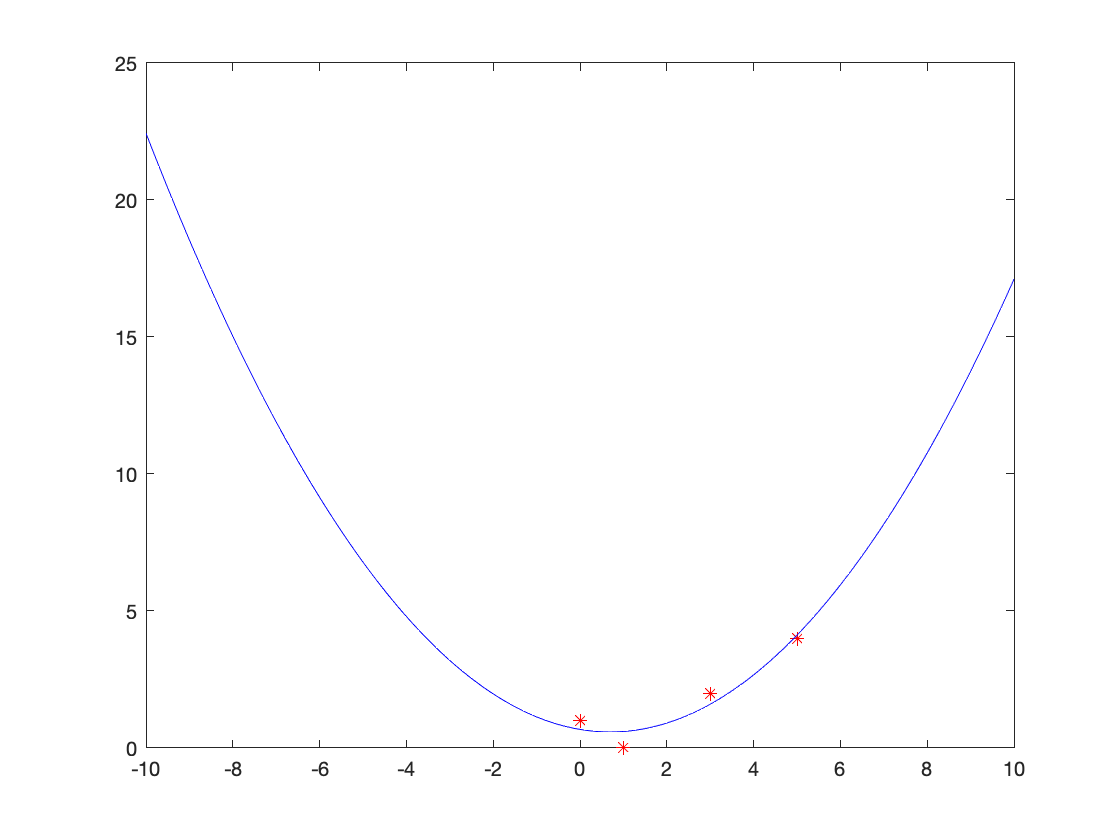

xes = -10:0.1:10; %max(x);
y = (p(1) * xes.^2) + (p(2) * xes) + p(3);
plot(xes, y, 'b-')
xlim([-10 10]);
hold off;

## 28.2.1

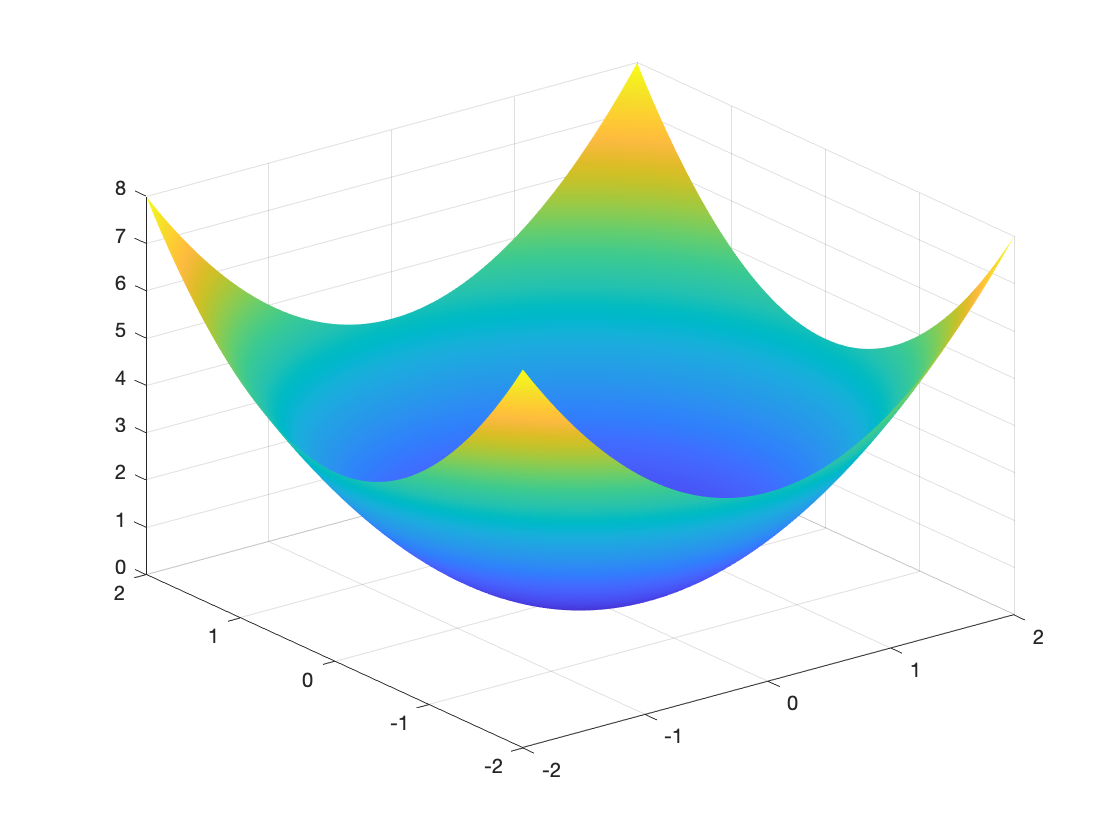

[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z = x.^2 + y.^2;
surf(x, y, z);
shading interp;

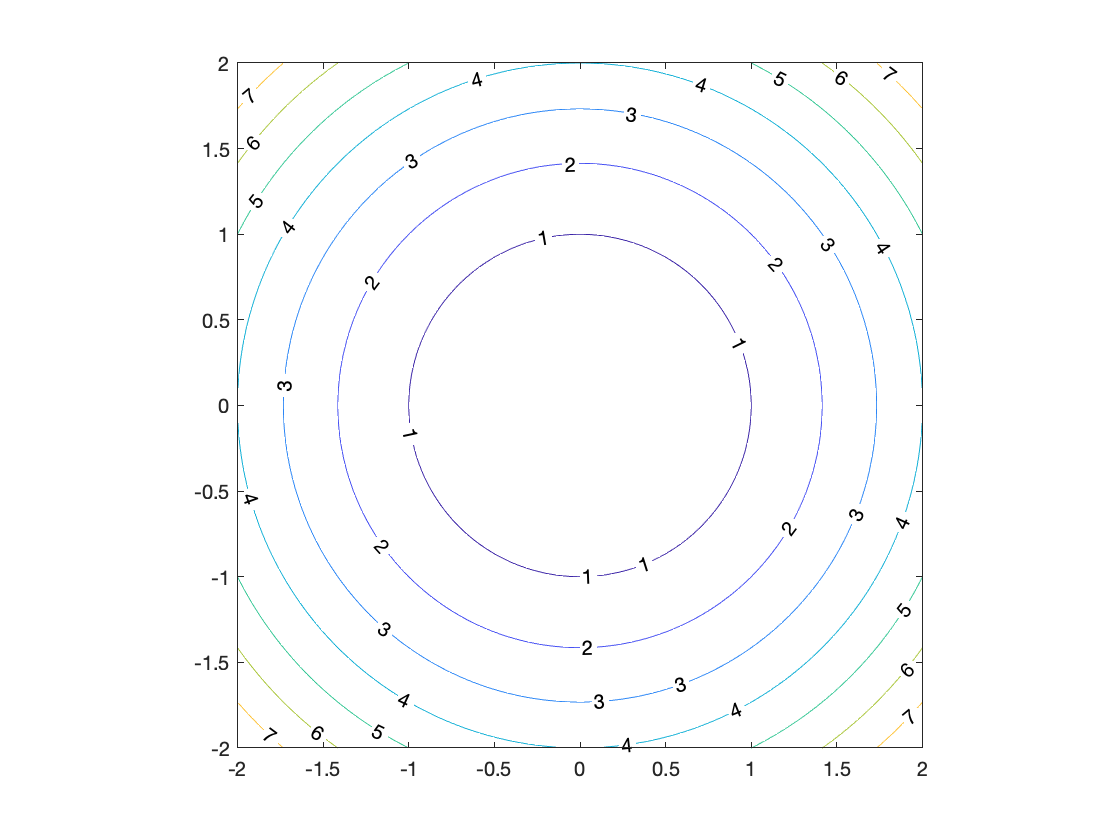

figure;
contour(x, y, z, "ShowText","on");
axis equal;

## Excercise 28.13

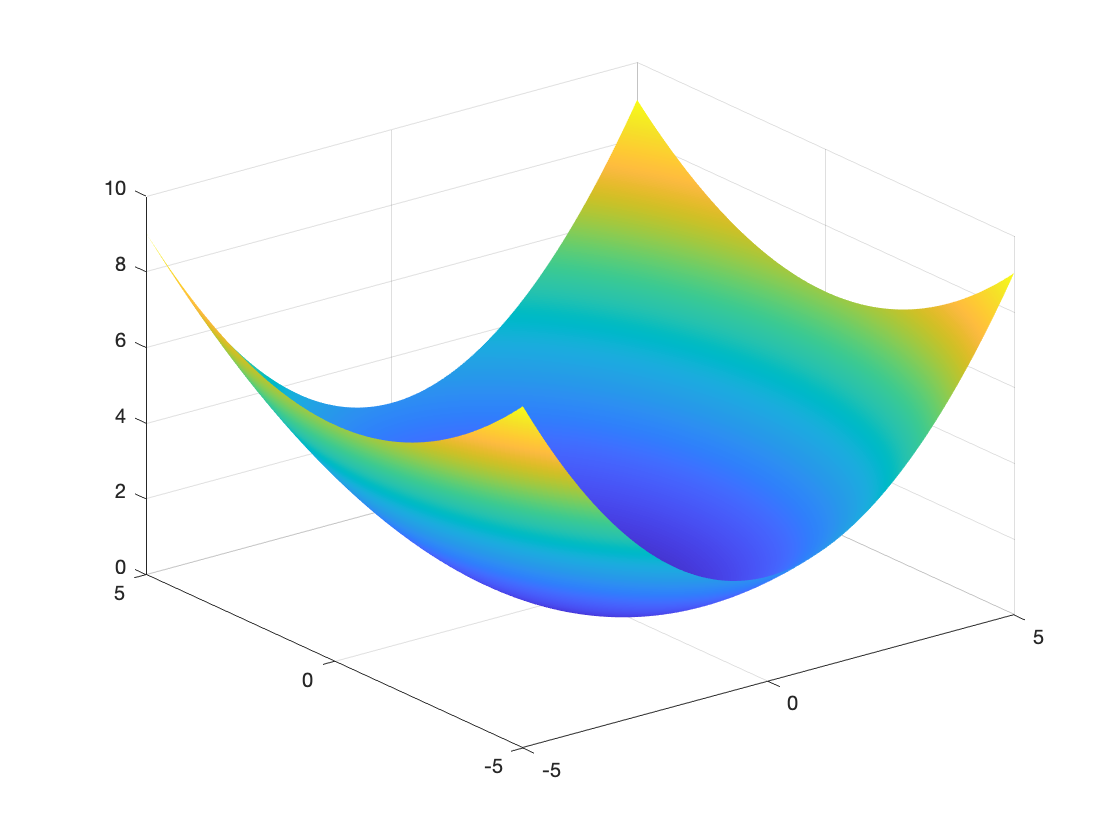

a = 2;
b = 3;

[x, y] = meshgrid(linspace(-5, 5, 100), linspace(-5, 5, 100));
z = (x.^2/a^2) + (y.^2/b^2);
surf(x, y, z);
shading interp;

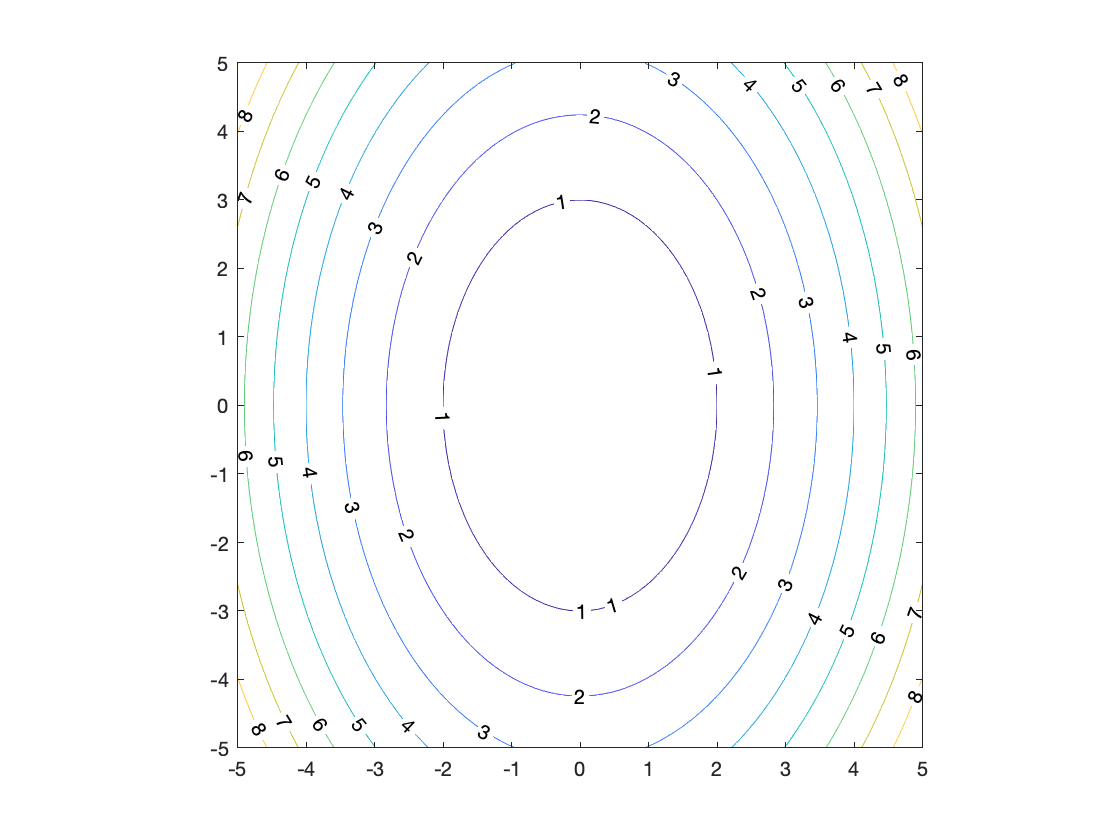

figure;
contour(x, y, z, "ShowText","on");
axis equal;

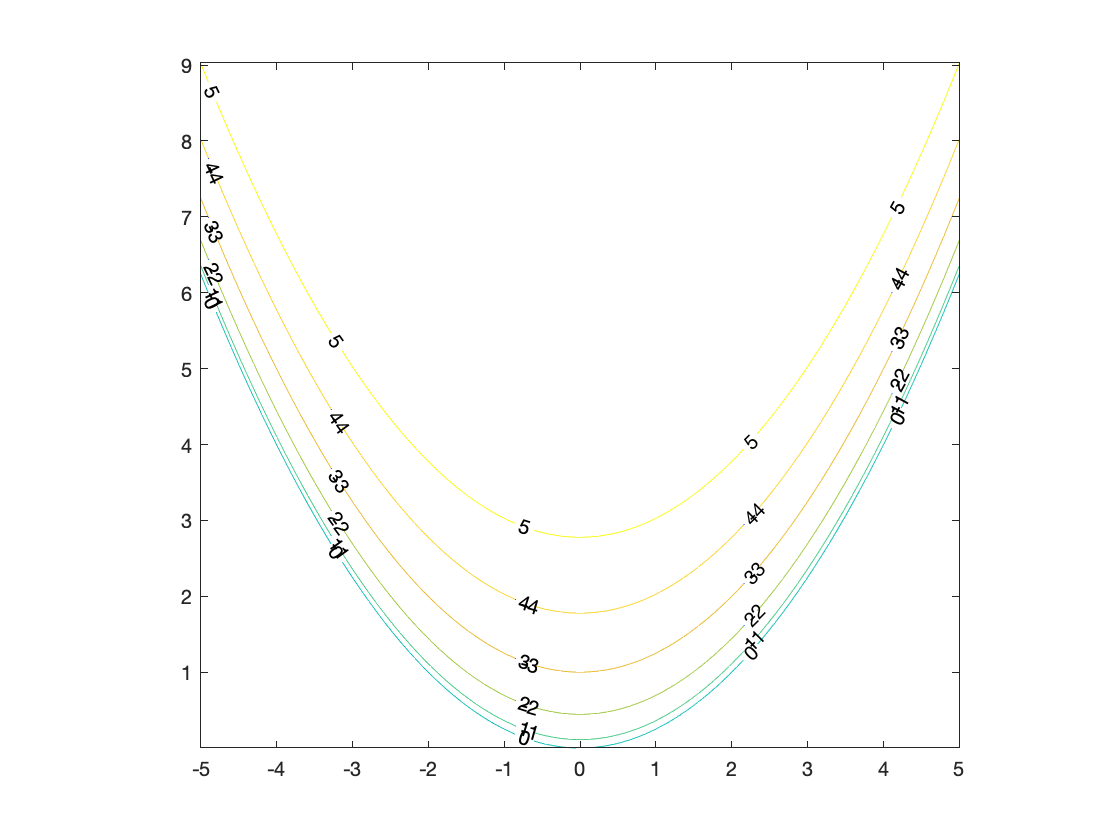


figure;
contour(x, z, y, "ShowText","on");
axis equal;

## 28.2.2

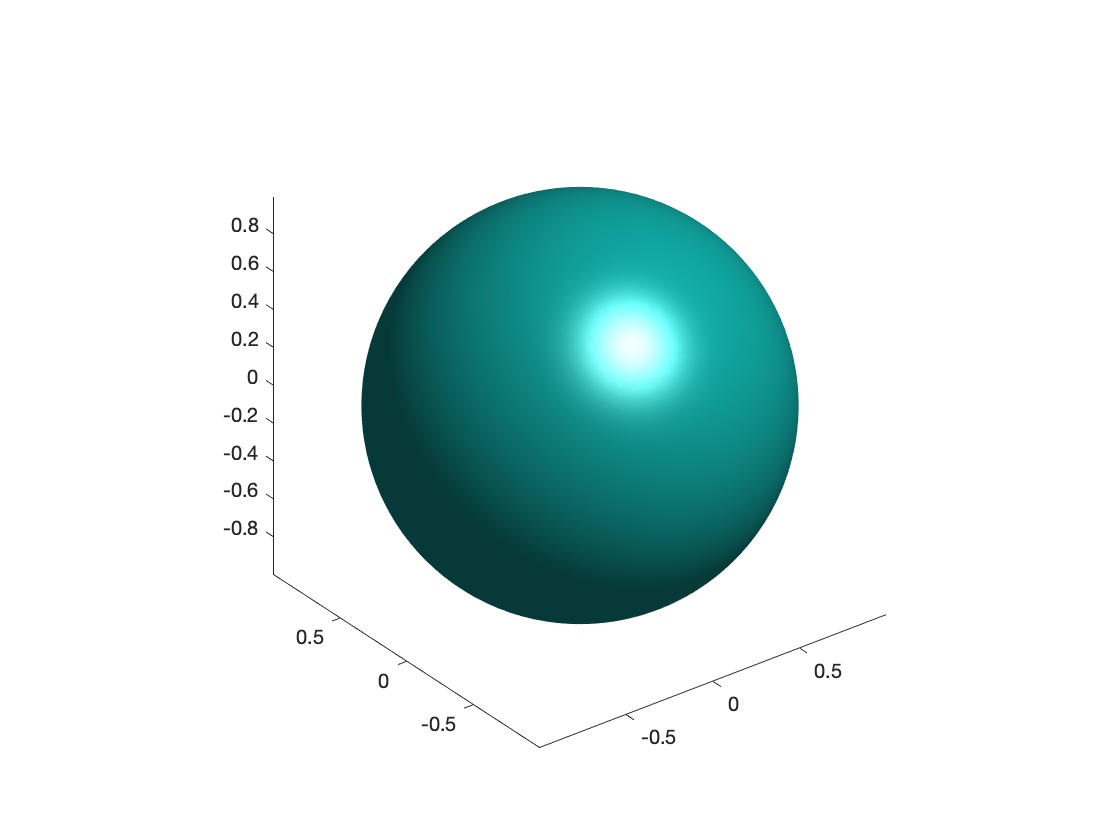

[x, y, z] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100), linspace(-2, 2, 100));
f = x .^2 + y .^2 + z .^2 - 1;
clf; isosurface(x, y, z, f, 0);
axis equal;

## Excercise 28.14

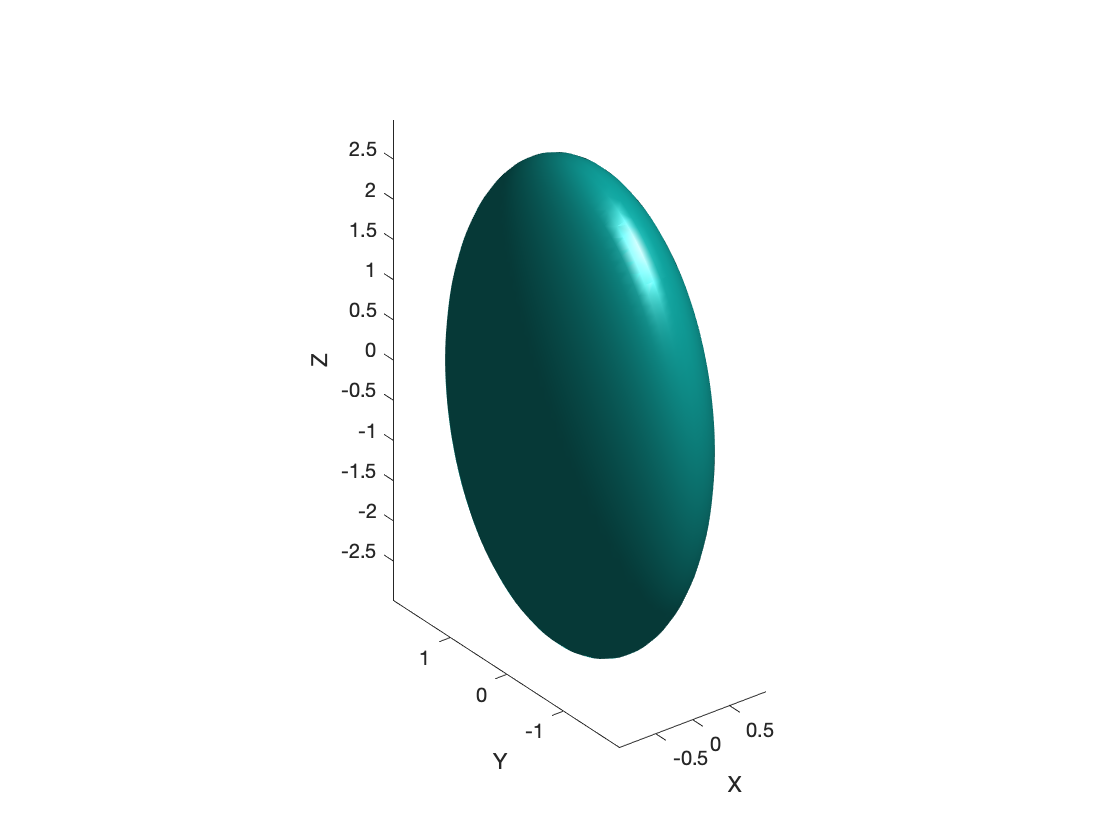

a = 1;
b = 2;
c = 3;
[x, y, z] = meshgrid(linspace(-5, 5, 100), linspace(-5, 5, 100), linspace(-5, 5, 100));
f = (x .^2 / a^2) + (y .^2 / b^2) + (z .^2 / c^2) - 1;
isosurface(x, y, z, f, 0);
axis equal;
xlabel("X"); ylabel("Y"); zlabel("Z");

## 28.2.3

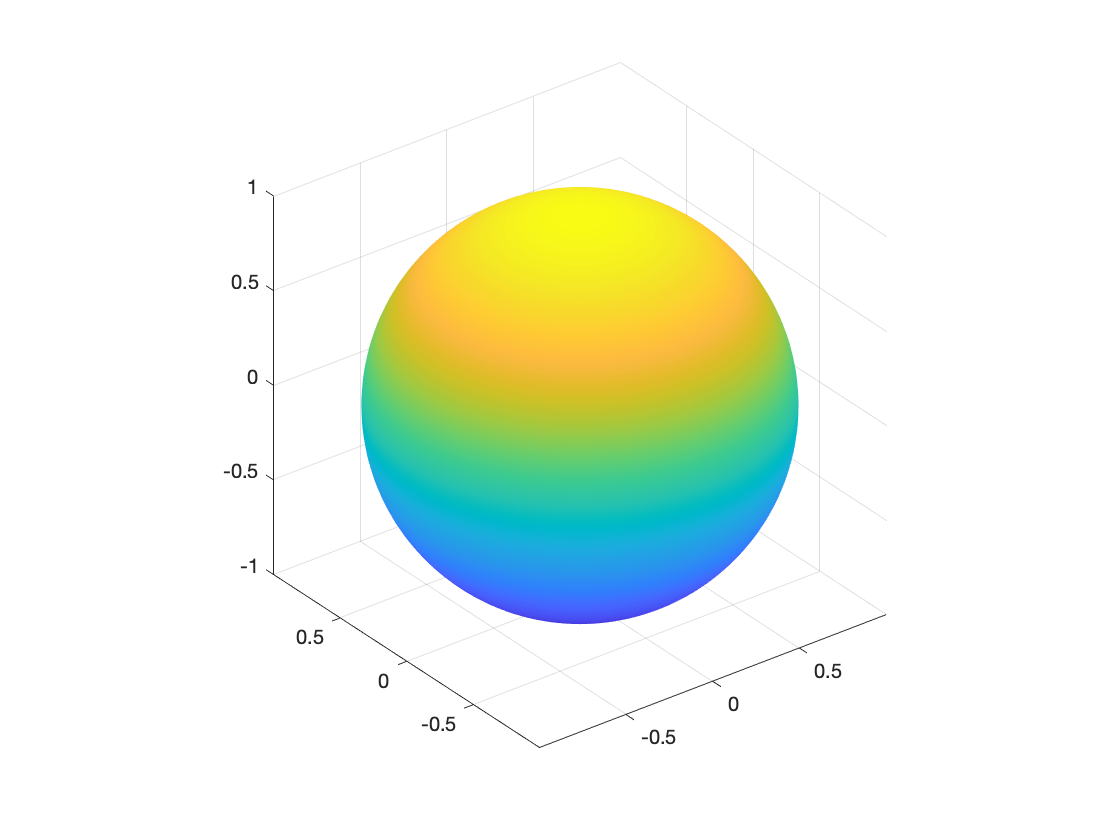

[u, v] = meshgrid(linspace(0, pi, 100), linspace(0, 2 * pi, 100));
x = sin(u) .* cos(v);
y = sin(u) .* sin(v);
z = cos(u);
surf(x, y, z); shading interp;
axis equal;

## Excercise 28.16

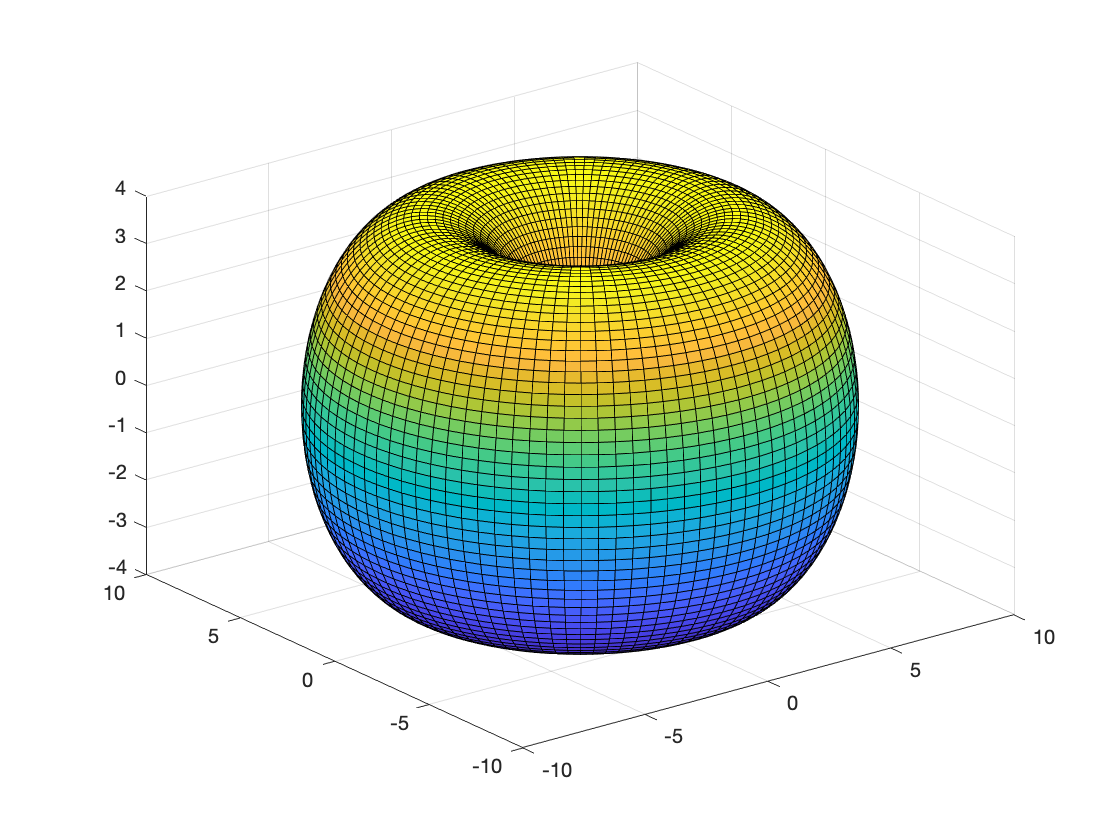

[u, v] = meshgrid(linspace(0, 2 * pi, 100), linspace(0, 2 * pi, 100));
a = 5;
r = 4;
x = (a + (r .* cos(u))) .* cos(v);
y = (a + (r .* cos(u))) .* sin(v);
z = r * sin(u);
surf(x, y, z);

## Excercise 28.17

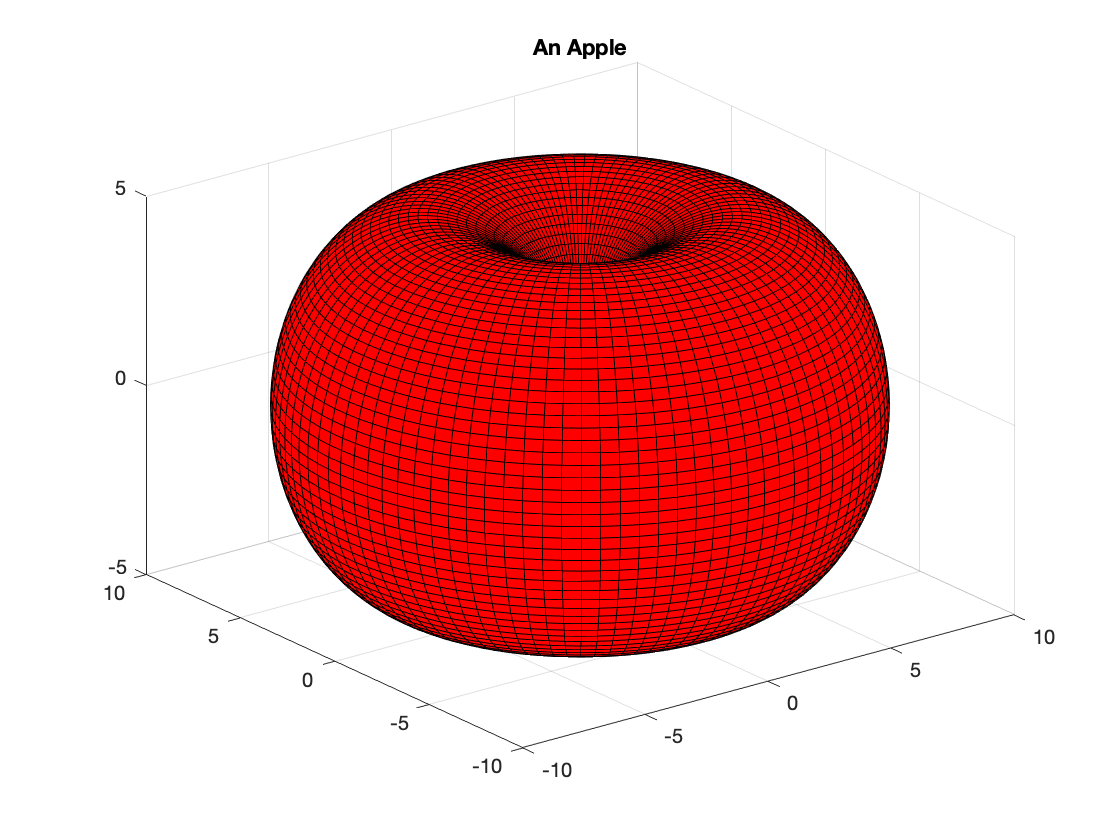

[u, v] = meshgrid(linspace(0, 2 * pi, 100), linspace(0, 2 * pi, 100));
a = 5;
r = 5;
x = (a + (r .* cos(u))) .* cos(v);
y = (a + (r .* cos(u))) .* sin(v);
z = r * sin(u);
surf(x, y, z);
title("An Apple")
colormap([1 0 0]);